## **AERO40003 Computing and Numerical Methods 1**

## **Coursework Project 2019-2020**

## **Dr. Maria Ribera Vicent & Dr. Elnaz Naghibi**

## **Due Date: 20 March 2020**

# PART 1 - MATLAB  [50%]

### Conduction: Temperature distribution on a 2-dimensional plate.   

There are three basic modes in which heat is transferred: conduction, convection and radiation. Conduction is the transfer of heat by virtue of the temperature gradients in the medium (you will learn more about heat transfer soon in your *Thermodynamics and Heat Transfer* module).

The heat conduction equation can be used to calculate the variation of temperature on the plate as a function of time, and after some assumptions  (i.e. constant thermal conductivity) it simplifies to:

$\frac{\partial T}{\partial t}=\alpha \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2} \right)$       (1)

where $\alpha$ is the thermal diffusivity of the material.

The time derivative can be discretise with some time step $\Delta t$ and equation (1) can be rewritten as:

$T(t+\Delta t) = T(t) + \alpha \Delta t \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2} \right)$       (2)

The spatial derivatives can also be approximated by finite differences, so that:

$\frac{\partial^2 T}{\partial x^2} \approx \frac{T(x-\Delta x,y) - 2 T(x,y) + T(x+\Delta x,y)}{\Delta x ^2}$           (3)


$$\frac{\partial^2 T}{\partial y^2} \approx \frac{T(x,y-\Delta y) - 2 T(x,y) + T(x,y+\Delta y)}{\Delta y ^2}$$


To solve the conduction equation above, all that is missing are the initial condition at time zero and/or some boundary conditions defining the temperature at the walls of the plate.

#### Part (a) [20%]

Consider a rectangular plate of a conductive material with dimensions w = 2m and h = 1m. Initially, this plate is at ambient temperature, 273K. Choose an adequate spatial discretisation for your domain.

The sides of the plate are suddenly and instantaneously heated. The left side of the plate is heated to 500K; the top side is heated to 400k; the bottom side is at 420K, while the right side as at 350K.

Plot the discretised domain and the initial temperature profile (use an adequate plotting function such as surf or contourf).

Iterate for 10 minutes. Use a time step of 0.1 seconds.

Display the temperature profile after 1 minute, 3 minutes, 5 minutes and 10 minutes.

Put labels and a title in your plots, and save as JPEG figures. 

Take $\alpha = 10^{-3} m^2/s$. 

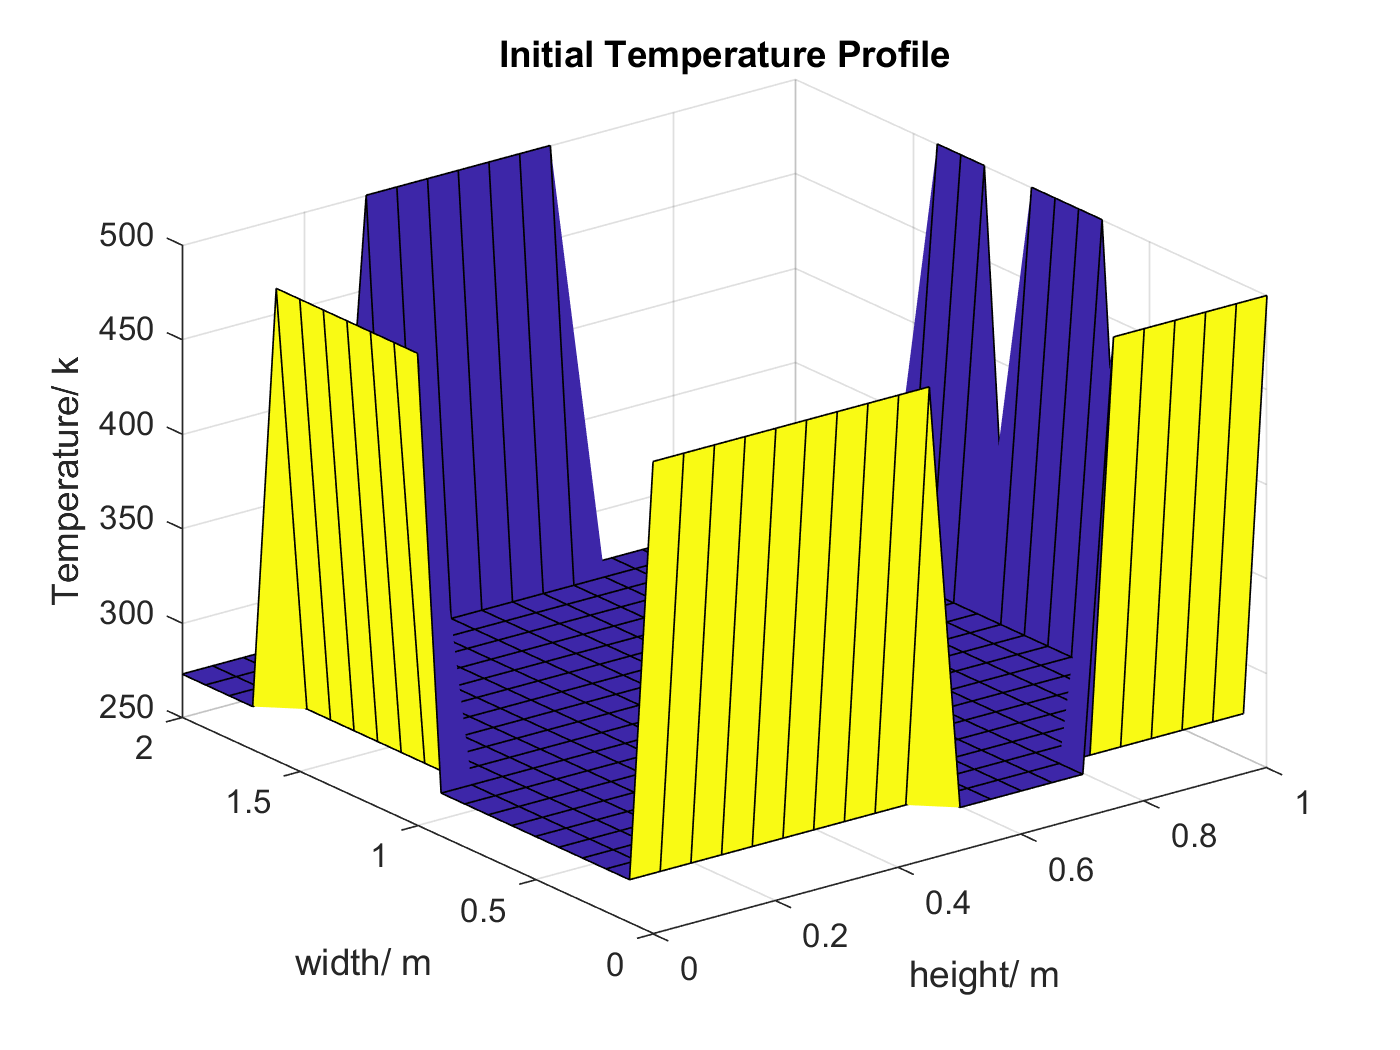

% Enter your code here
% If you need to write any functions, please save them in a separate .m
% file.
clc
clear
close all

w=2;              % width of the plate
h=1;              %height of the plate
deltaT=0.1;       %timestep of 0.1 seconds
Alpha=10^(-3);    % thermal diffusivity of the material
t=600;            % iteration time of 10 minutes
Nt=t/deltaT;      % number of time steps

Nx=21;           %number of x discretisations
Ny=21;            %number of y discretisations
deltaX=w/(Nx-1);  % x spatial step
deltaY=h/(Ny-1);  % y spatial step

% create spatial discretisation
[Y,X] = meshgrid(0:deltaY:h,0:deltaX:w);

%initiate temperature array with spatial 
% discretisation and third dimension for time iterations for efficiency
T(1:Nx,1:Ny,1:Nt+1)=273;



% apply initial boundary conditions based on user choice
% coordinates system has interval equivalent of deltaX in the x direction
% and deltaY in the y direction
% Apply switch statement for user to decide the initiation scheme
choice=double(input('would you like to run the uniform temperature for each side simulation (1) or the nodal one (2)'));
switch choice
  case 1
    T(1,:,:)=500;
    T(Nx,:,:)=350;
    T(:,1,:)=420;
    T(:,Ny,:)=400;
  case 2
    T(1,1:10,:)=500;
    T(1,16:21,:)=500;
    T(11:17,1,:)=500;
    T(8:11,21,:)=500;
    T(13:15,21,:)=500;
    T(21,7:13,:)=500;    
end

% iterate through time steps saving each iteration of the Plate temperatures
% to allow access to each step later
for n=1:Nt     % time iteration
    for i=2:Nx-1  % x iteration
        for j=2:Ny-1  % y iteration
            % calculate each timestep's temperature accross the plate
          T_xx=(T(i-1,j,n)-2*T(i,j,n)+T(i+1,j,n))/deltaX^2;
          T_yy=(T(i,j-1,n)-2*T(i,j,n)+T(i,j+1,n))/deltaY^2;
          T(i ,j, n+1)=  T(i,j,n)+Alpha*deltaT*(T_yy+T_xx);
        end
    end
end

% plot initialtemperature profile
surf(Y,X,T(:,:,1))
title('Initial Temperature Profile')
xlabel('height/ m')
ylabel('width/ m')
zlabel('Temperature/ k')

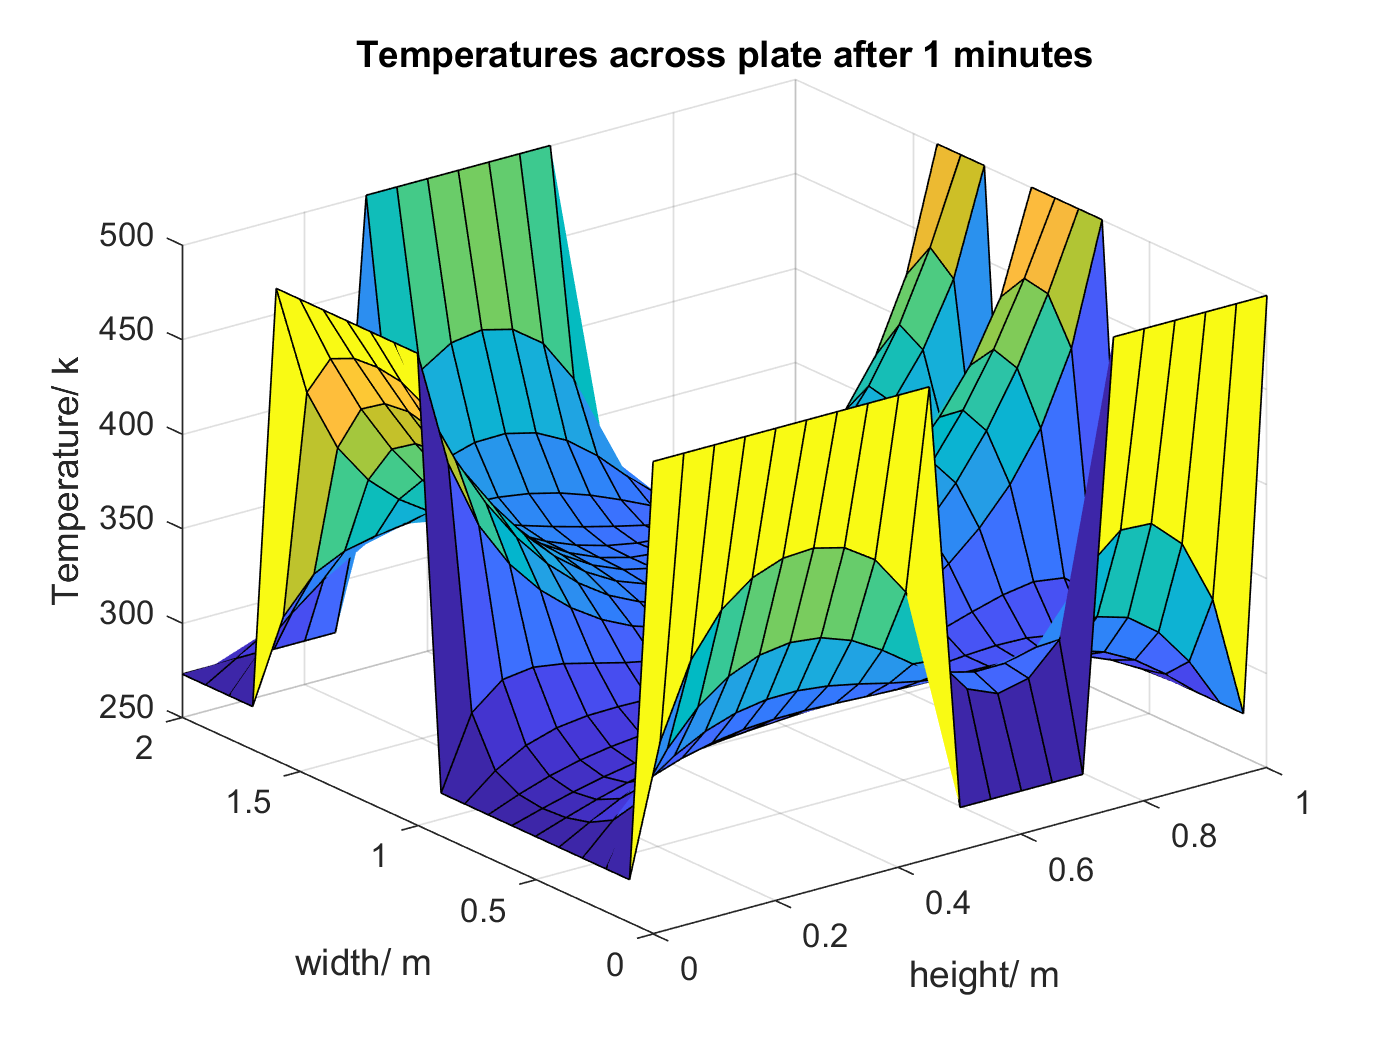


% display plate temperatures after 1,3,5 and 10 minutes
surf(Y,X,T(:,:,601))
title('Temperatures across plate after 1 minutes')
xlabel('height/ m')
ylabel('width/ m')
zlabel('Temperature/ k')

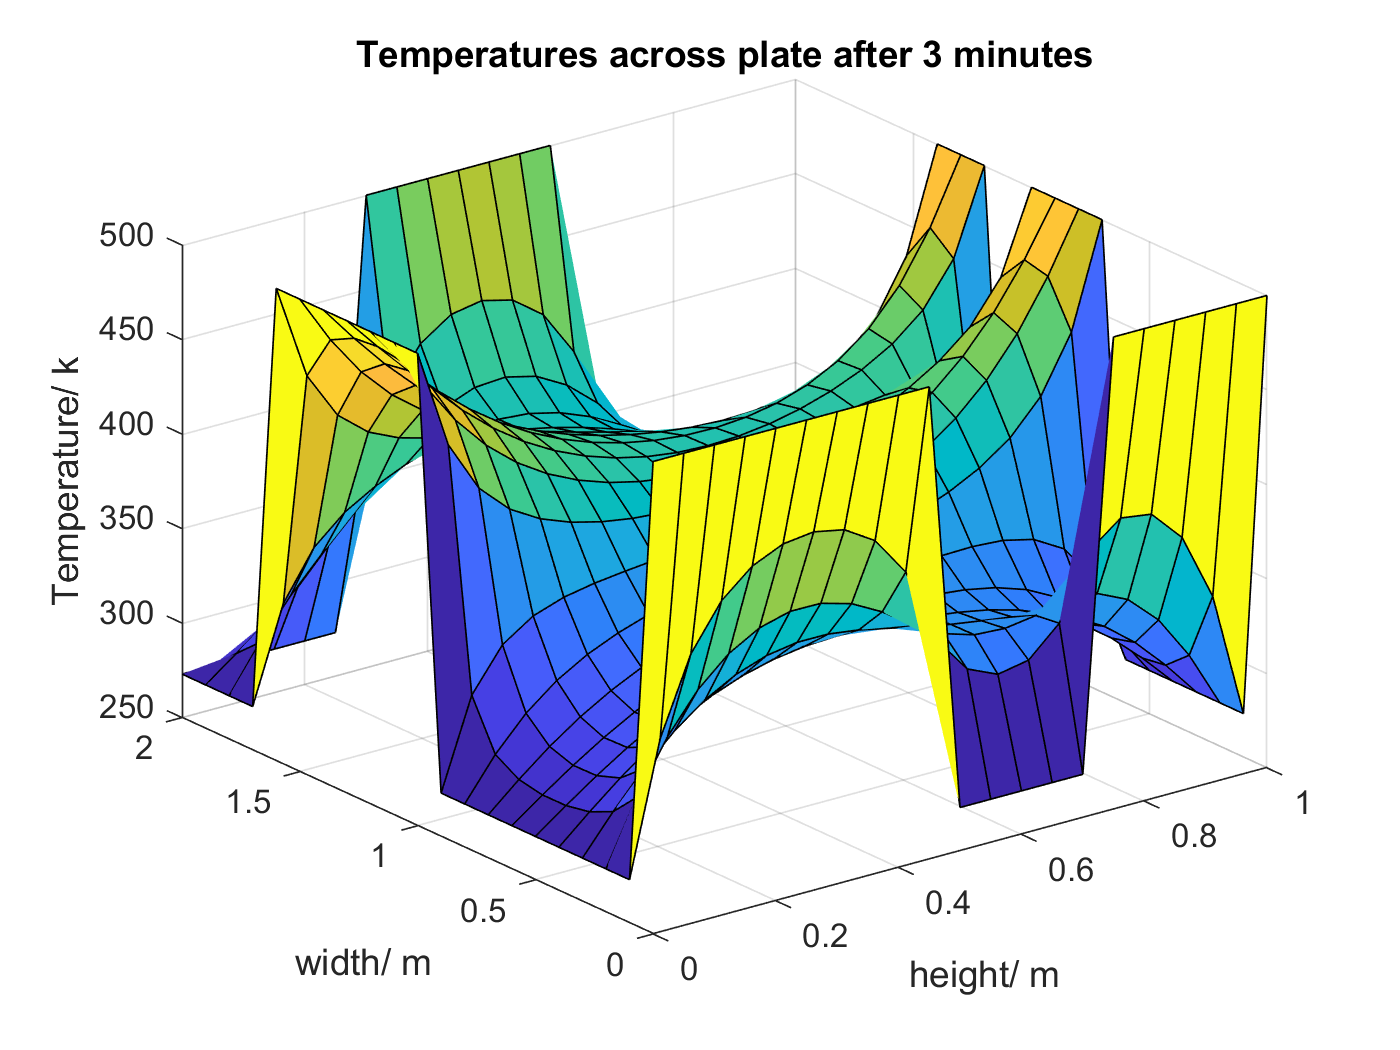


surf(Y,X,T(:,:,1801))
title('Temperatures across plate after 3 minutes')
xlabel('height/ m')
ylabel('width/ m')
zlabel('Temperature/ k')

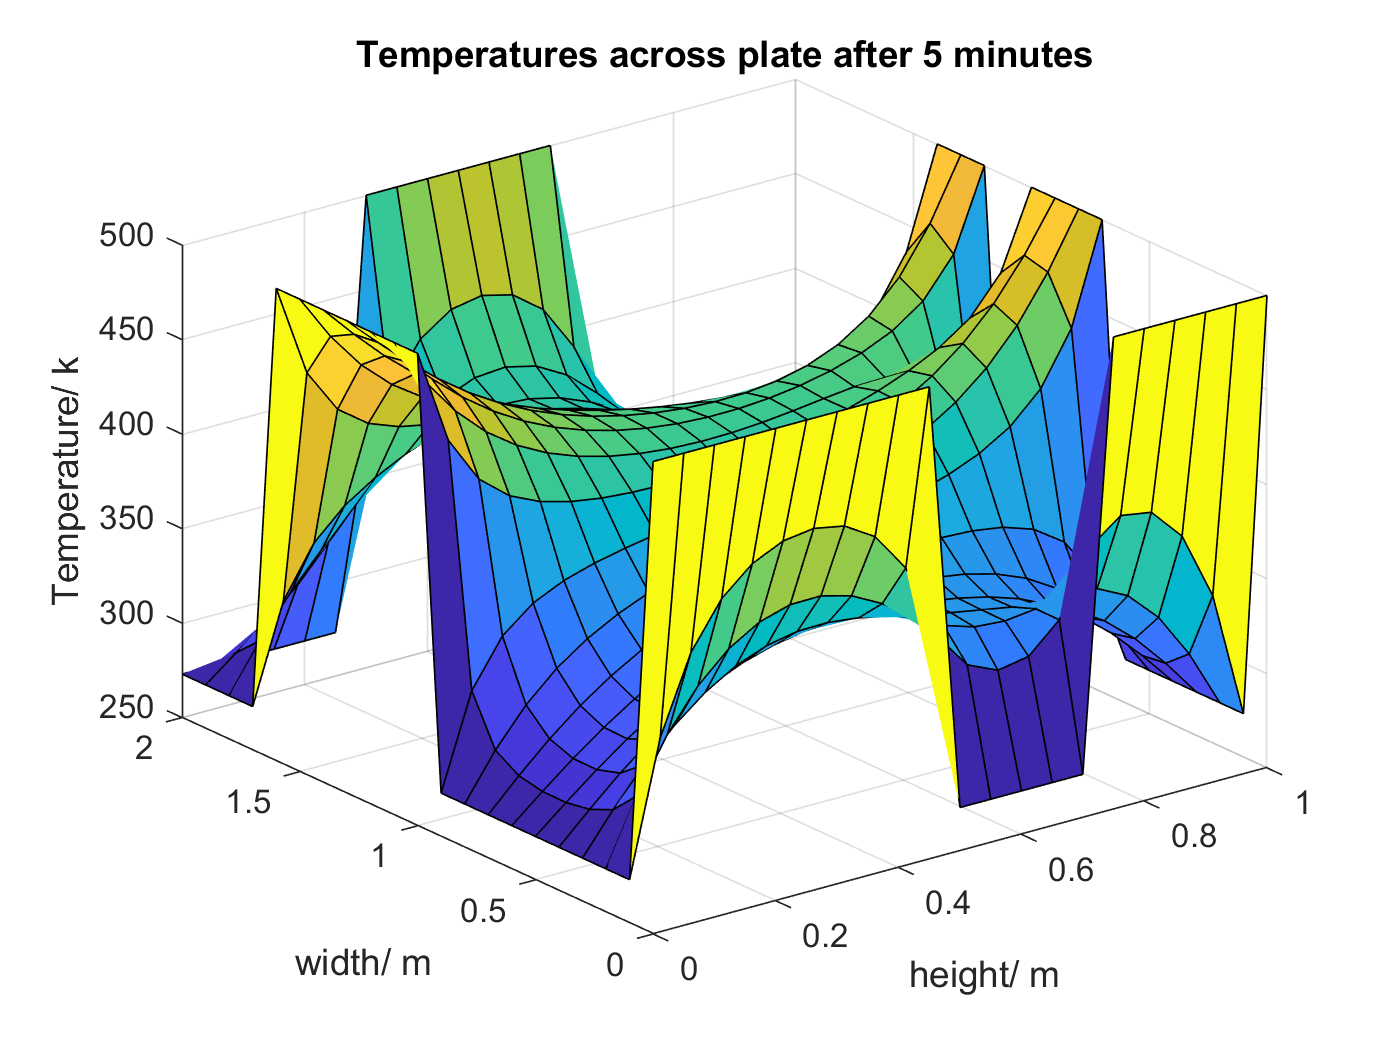


surf(Y,X,T(:,:,3001))
xlabel('height/ m')
ylabel('width/ m')
zlabel('Temperature/ k')
title('Temperatures across plate after 5 minutes')

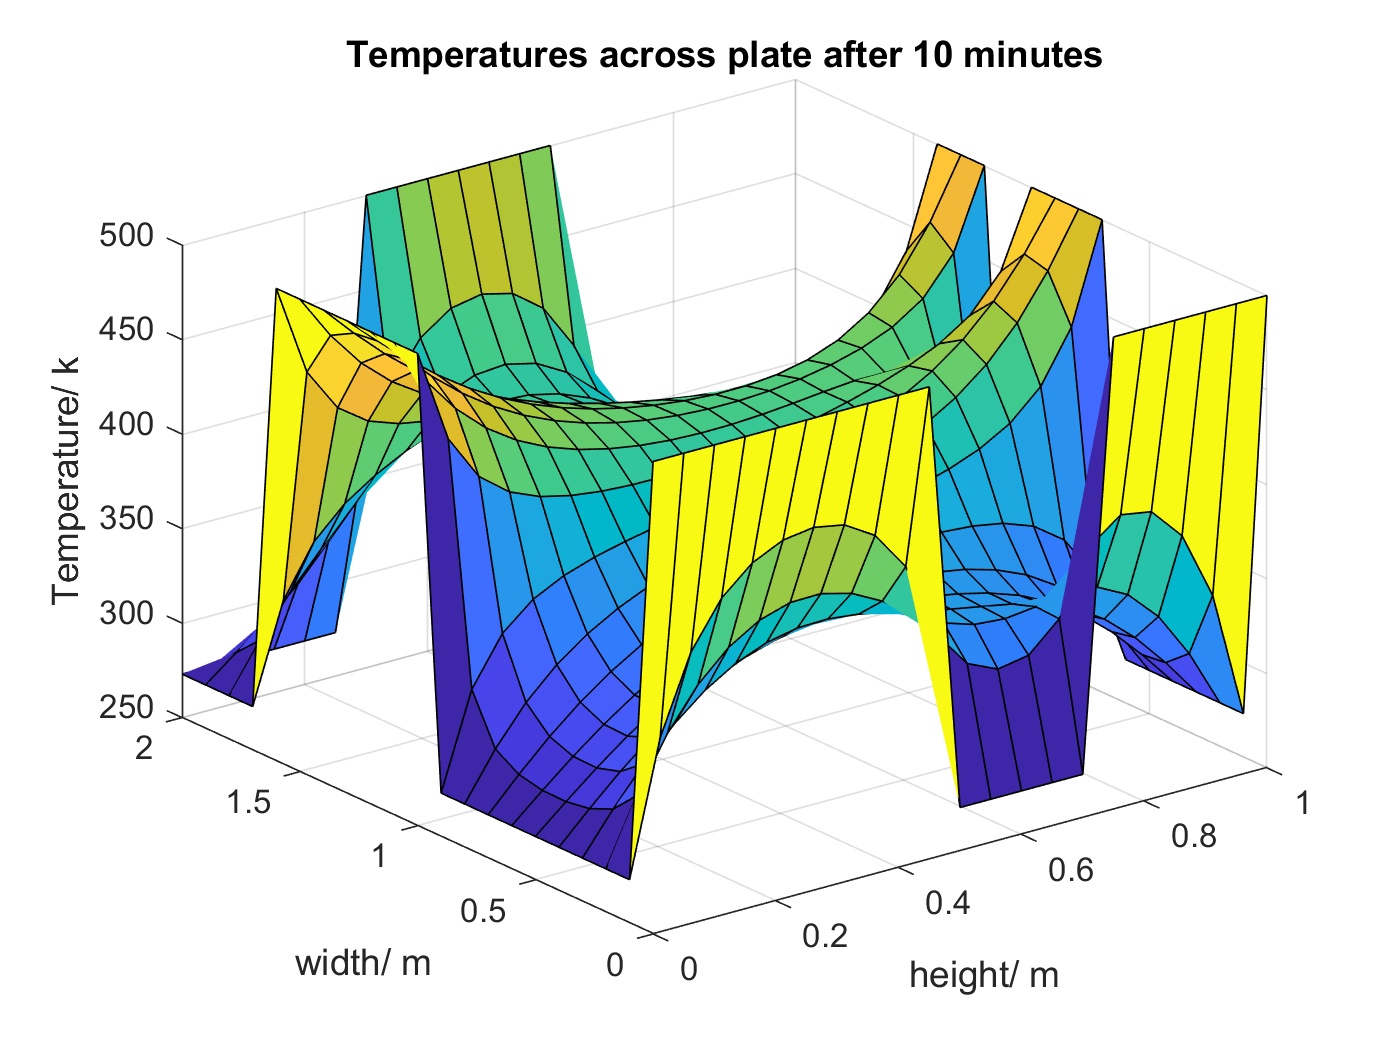


surf(Y,X,T(:,:,6001))
xlabel('height/ m')
ylabel('width/ m')
zlabel('Temperature/ k')
title('Temperatures across plate after 10 minutes')

#### Part (b) [10%]

Use the function **fit** to obtain a surface to approximate the data in part (a) after 1 minute. There are many[ types of surface fit](https://uk.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html)  possible, try with two different types of your choice (i.e. interpolant, polynomial...). Make sure you output the goodness-of-fit statistics of each surface approximation (see the [documentation](https://uk.mathworks.com/help/curvefit/fit.html) for explanation). 

Which of the two gives the better approximation to your data? Explain briefly. 

Plot both surfaces in separate plots, with the corresponding labels and title. Save as a JPEG file.

In a single figure, plot the values of both functions along the line y=0.5 for all values of x (i.e., the line that splits the plate in half), along with the original points from part (a) at the same location. Make sure you add labels, title and a legend. Save the figures as JPEG file.

Hints: 

- the function **fit** requires the input in columns, so reorganise your data to have both the coordinates and the temperature each in a column vector. 

- save the data above corresponding to the first minute in a separate array to use later.

- The output of the **fit** function is a *sfit* object, which works similarly to function handles. You can read more about them in [here](https://uk.mathworks.com/help/curvefit/sfit.html).

%create variables to store x and y coordinates as well as
% temperatures at 1 minute in column vector form to enable fits
Xcol=X(:);
Ycol=Y(:);
v=T(:,:,601);
Tcol=v(:);

% calcualting a fit using local linear regression and surface plotting
[fitobject1,goodfit1] = fit([Ycol,Xcol],Tcol,'lowess');
goodfit1

goodfit1 = struct with fields:
           sse: 7.0919e+05
       rsquare: 0.6049
           dfe: 431.0541
    adjrsquare: 0.5967
          rmse: 40.5617


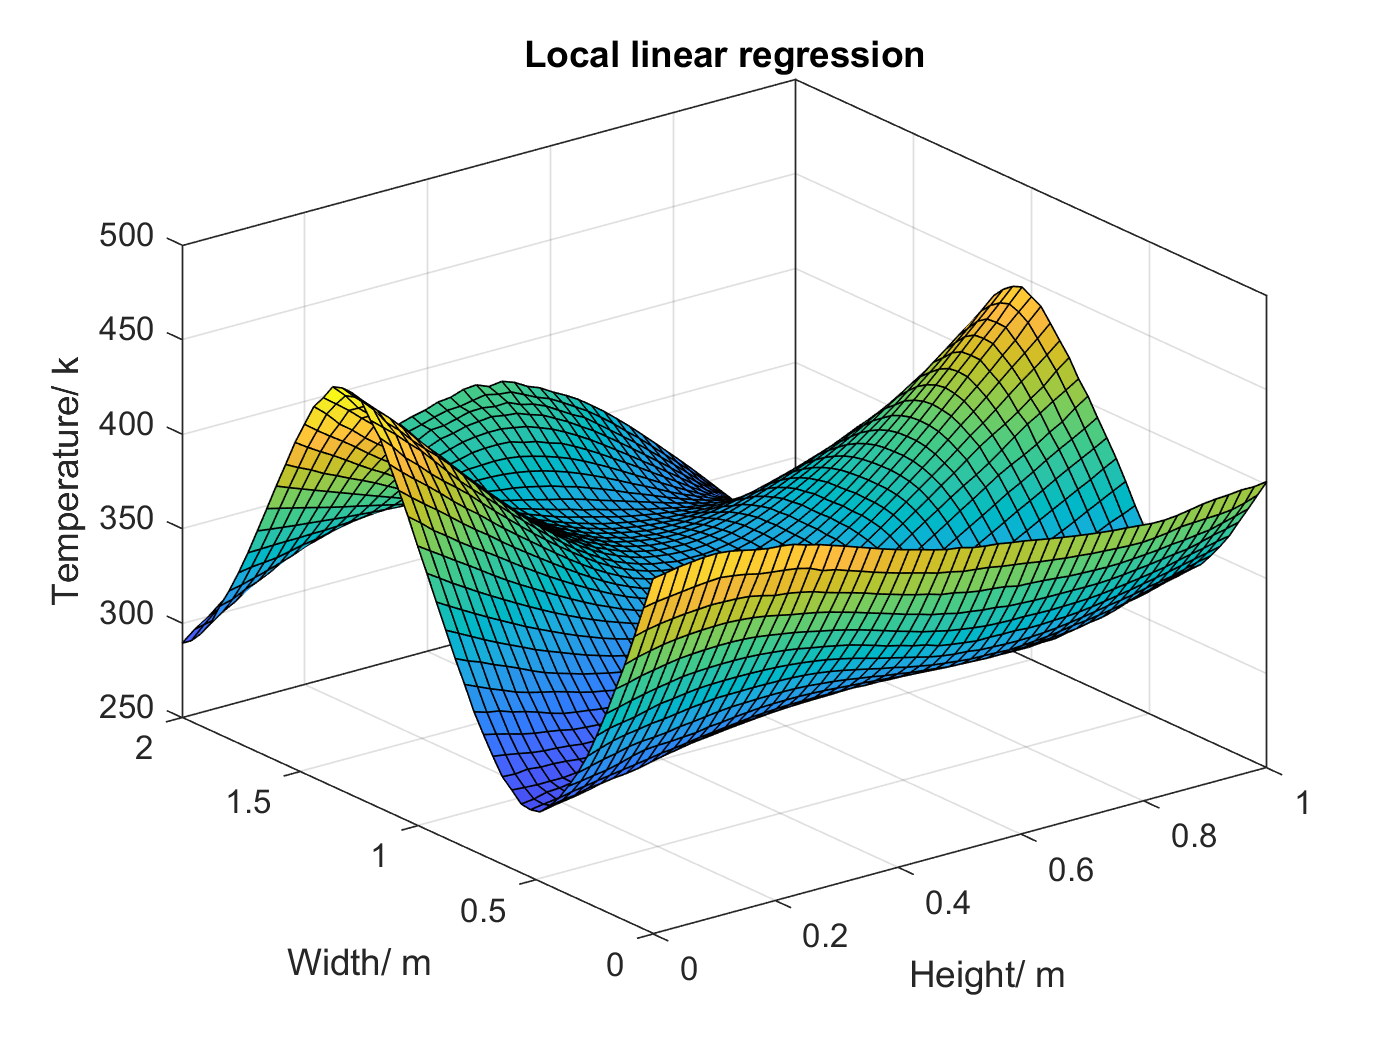

plot(fitobject1)
title('Local linear regression')
ylabel('Width/ m')
xlabel('Height/ m')
zlabel('Temperature/ k')


% calcualting a fit using 5th degree polynomial regression and surface plotting
[fitobject2,goodfit2] = fit([Ycol,Xcol],Tcol,'poly55');
goodfit2

goodfit2 = struct with fields:
           sse: 4.9881e+05
       rsquare: 0.7221
           dfe: 420
    adjrsquare: 0.7089
          rmse: 34.4623


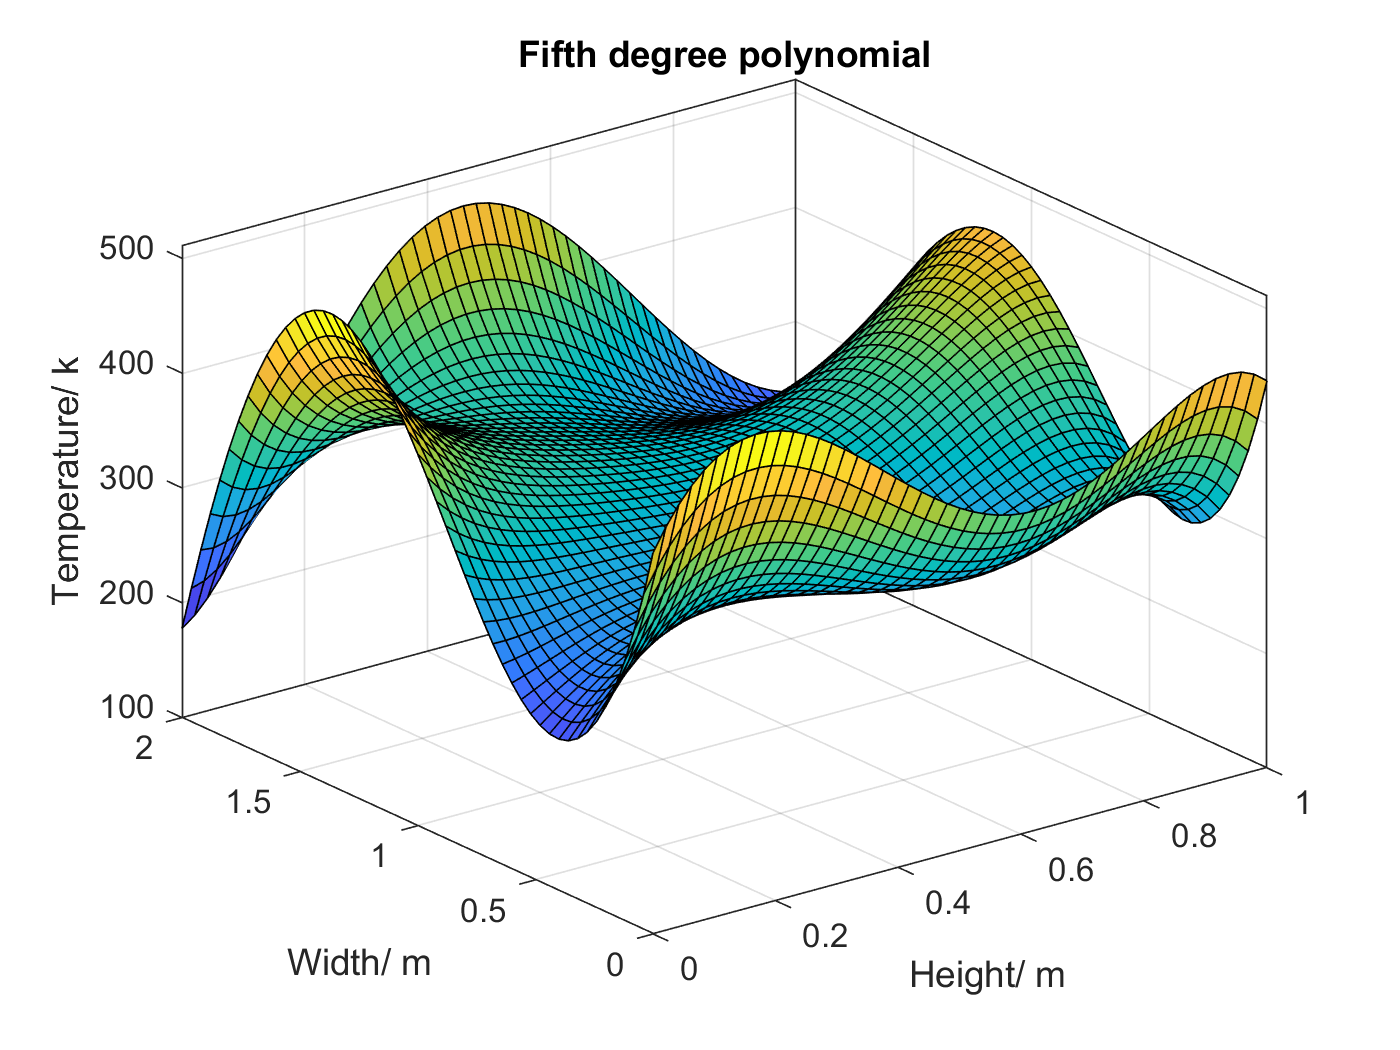

plot(fitobject2)
title('Fifth degree polynomial')
ylabel('Width/ m')
xlabel('Height/ m')
zlabel('Temperature/ k')


% calculate root mean square for each surface fit to allow fit comparison
p=goodfit2.rmse-goodfit1.rmse;
if p<0
    disp(['since the Local linear regression had a lower root mean square of error' ...
        ' value, it was the more accurate fit'])
elseif p==0
        disp(['since the Local linear regression had the same root mean square of error' ...
        ' value as the fifth degree polynomial, they are equally accurate fits'])
else
        disp(['since the Fifth degree polynomial had a lower root mean square of error' ...
        ' value, it was the more accurate fit'])
end

since the Local linear regression had a lower root mean square of error value, it was the more accurate fit


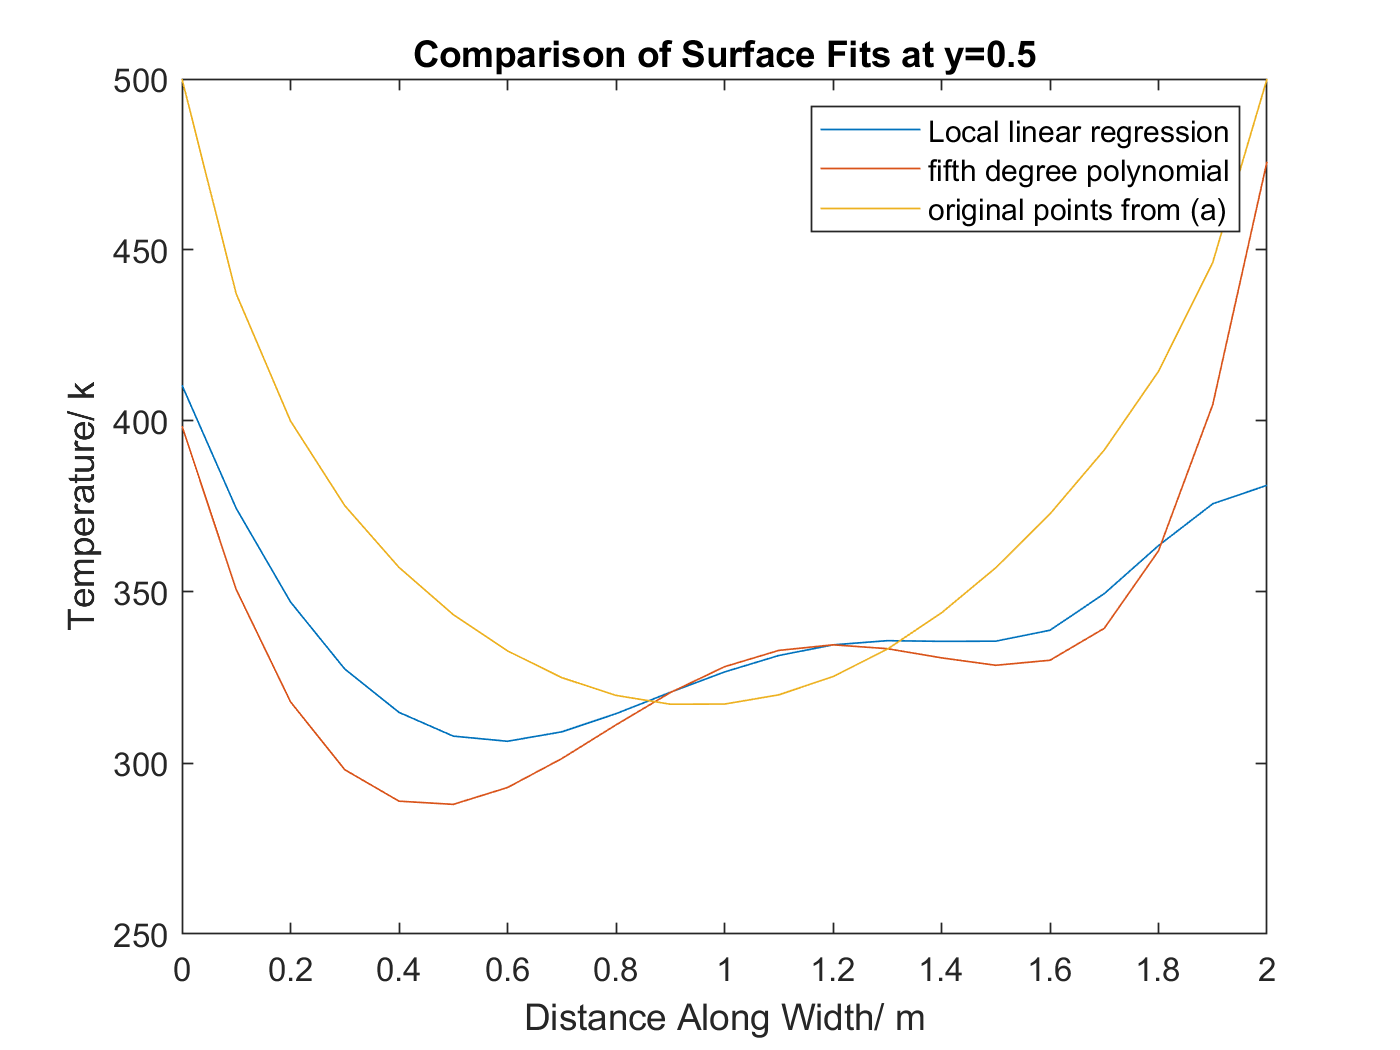


% plot the two fits at y=0.5 on same graph for comparison
plot(X(:,11),fitobject1(Y(:,11),X(:,11)))
hold on 
plot(X(:,11),fitobject2(Y(:,11),X(:,11)))
plot(X(:,11),T(11,:,601))
title('Comparison of Surface Fits at y=0.5')
legend('Local linear regression','fifth degree polynomial','original points from (a)')
xlabel('Distance Along Width/ m')
ylabel('Temperature/ k')

#### Part (c) [10%]

Use the **fmincon** function to find the minimum temperature in the plate above, and the location where it occurs, in the same snapshot after 1 minute. (Note: we are not applying any constraints other than the bounds on the x and y dimensions so that the search takes place within the plate; all the other input to fmincon must be defined, but can be an empty array - see [documention](https://uk.mathworks.com/help/optim/ug/fmincon.html) for examples).

Start your search from the point [2,1], corresponding to the upper right corner.

Display your answer neatly (you may use **disp** or **fprintf** but either case format your string nicely)

Hint: remember you can use the* sfit* object as a function handle when using** fmincon**. 

***OPTIONAL, for fun :)***

*You can play with the options to fmincon, for instance you can display all the iterations in the search.*

*You could also explore what other outputs you can get from the function in structures that group different values of interest, such as the gradient of the function at the solution or the Lagrange multipliers.*


% creating conditions for fmincon
A = [];
b = [];
Aeq = [];
beq = [];

% running fmincon to find coordinates of min temp
% only searching within the plate
% starting from upper right coordinate of plate for part a
% and starting from top left of plate for part d

switch choice
  case 1
    x = fmincon(fitobject1,[1,2],A,b,Aeq,beq,[0,0],[1,2]);
  case 2
    x = fmincon(fitobject1,[1,0],A,b,Aeq,beq,[0,0],[1,2]);   
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% displaying coordinates and temperature at that point
disp(['The coordinates of the local minima at t= 1 minute are ', num2str(x(2)), ' and ', num2str(x(1))])

The coordinates of the local minima at t= 1 minute are 0.49316 and 2.7558e-08


disp(['At these coordinates, the temperature is ', num2str(fitobject1(x(1),x(2))), ' kelvin'])

At these coordinates, the temperature is 286.801 kelvin


#### Part (d) [10%] 

Now repeat the above with different boundary conditions. Rather than a uniform temperature for each side, we consider the entire plate at ambient temperature except the following nodes/regions that will be heated to 500K:

T(0,0-0.45) = 500K

T(0,0.75-1) = 500K

T(1-1.6,0) = 500K

T(1-0.7,1)= 500K

T(1.2-1.7,1)= 500K

T(2,0.3-0.6) = 500K

Rather than repeating the entire code again, you may **choose one** of the following two options: 

- Ask the user which case to run, then use a switch to define the boundary conditions.   or

- Use a loop to repeat the process for each set of boundary conditions.

Do the approximation functions you used for part (b) work as well in this part? If not, consider using a higher degree polynomial or other functions to give you a better fit.

Start the search of the minimum from [0,1], corresponding to the top left corner. 

Hints: 

- make sure you don't overwrite your saved figures.

- you could also use your condition to have the different starting values in each case.

***Some general tips:***

- make sure you don't overwrite your figures!

- look at your results and see if they make sense. If not, what can you change? the step size? the type or degree of the interpolating function? While an exact interpolant for part (d) might be difficult, at least think about it.

- read the markscheme and make sure that your code is well commented and indented.

- when asked to save the figures, remember to put them in your folder together with your livescripts, before zipping and uploading the compressed folder. 